
clear all;
% close all;
path = 'D:\MATLAB_Git\MATLAB-atomic-calculation\Monopole-dipole\';
addpath(path);
path_curve = 'D:\MATLAB_Git\MATLAB-atomic-calculation\Monopole-dipole\curve\';
curve1 = load([path_curve,'he.txt']);
curve2 = load([path_curve,'Maglab1.txt']);
curve3 = load([path_curve,'NG.txt']);
curve4 = load([path_curve,'PTB.txt']);



maindir='\\Artemis-pc\Data\2026-08-10\';   % 储存地址
save_data = 0;

zMin = 72+5;%um
zMax = 226-108;

multiplier = 1.3;
lambda0 = 20;   % um, lambda min
lambdaFinal = 40;   % um, lambda max
len = floor(log(lambdaFinal/lambda0)/log(multiplier))+1;

mass_length = 6000;%um
mass_span = 800; %um; Along k vector;

atoms_length = 20.4; %um; Atom along k vector
atoms_width = 15.4; %um; along Beam waist
sample = 120;

xmin = 10e-6;
xmax = 150e-6;
ymin = 1e-24;
ymax = 3e-17;



% omega1 = 2*pi*9.2318;
% omega2 = 2*pi*12.8177;
omega1 = -2*pi*9.2318*10;
omega2 = 2*pi*12.8177*10;

%deltaX = 2*pi*10e-5; %3hours
deltaX = 2*pi*(33+142*2)*1e-6;   % test 1 day 2 sigma
%deltaX = 2*5e-7*omega2;%/sqrt(1200)/sqrt(20)*sqrt(3)/2;

%deltaX = 2*pi/sqrt(1000*28*10*20)/15;%100 hours
hbar = 6.6260755e-34/(2*pi);%Constant.ReducedPlanck;
Na=Constant.AvogadroNumber;
mn=Constant.AtomicMass;
rho_pt=21.45; % g/cm^3
n=rho_pt/1000/mn*10^6; % /m^3

%c1 = -1/3;
%c2 = -0.143;

c1 = -0.3;
c2 = -0.0456;



geo = zeros(length(zMin),len,sample);
for j=1:length(zMin)
    for k=1:len
        lambda(k) = lambda0*multiplier^(k-1);
        %lambda(len)=26.5;
        sum=0;
        parfor i=1:sample
            x0=randn*atoms_length/2;
            y0=randn*atoms_width/2;
            z0=randn*atoms_width/2;
            geo(j,k,i) = ...
                geofactor(lambda(k),zMin(j),x0,y0,z0,mass_length,mass_span)-...
                geofactor(lambda(k),zMax,x0,y0,z0,mass_length,mass_span);
        end    
        k
    end
end

k = 1

k = 2

k = 3


g_factor=mean(geo,3);
g_error=std(geo,0,3)./sqrt(sample-1);
g_factor=g_factor*10^(-6);
g_error=g_error*10^(-6);


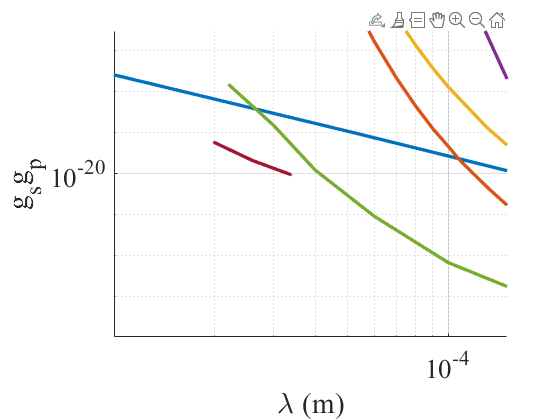


f1 = figure; hold on;
lw = 2.5;
plot(curve1(:,1),curve1(:,2),'LineWidth',lw);
plot(curve2(:,1),curve2(:,2),'LineWidth',lw);
plot(curve3(:,1),curve3(:,2),'LineWidth',lw);
plot(curve4(:,1),curve4(:,2),'LineWidth',lw);
load('ning_data.mat');
plot(ning_data(:,1),ning_data(:,2)*3,'LineWidth',lw);

for i=1:length(zMin)
    gsgp(:)=deltaX./(hbar*n*(c1*omega2-c2*omega1)./(8*pi*mn*omega2).*g_factor(i,:));
    gsgp_error(:)=deltaX./(hbar*n*(c1*omega2-c2*omega1)./(8*pi*mn*omega2).*g_factor(i,:).^2).*g_error(i,:);
    l=plot(lambda.*10^(-6),abs(gsgp),'.-');
    l=errorbar(lambda.*10^(-6),abs(gsgp),gsgp_error);
    set(l,'linewidth',lw,'CapSize',0,'MarkerSize',2);
end

set(gca,'XScale','log','YScale','log','fontsize',20)
set(gca,'fontname','times new roman')
xlabel('\lambda (m)')
ylabel('g_sg_p')

%legend('3um','5um')
xlim([xmin xmax]);
ylim([ymin ymax]);
grid on;

set(f1,'Visible','on');


if save_data == 1
    save([maindir,'20um_real.mat']);
    saveas(f1,[maindir,'20um_real.png']);
    savefig(f1,[maindir,'20um_real.fig']);
end


function output = geofactor(lambda,zMin,x0,y0,z0,mass_length,mass_span)
    fun = @(x,y,z) (1./(distance(x,y,z,x0,y0,z0).*lambda) + 1./distance(x,y,z,x0,y0,z0).^2).*...
    exp(-distance(x,y,z,x0,y0,z0)./lambda).*z./distance(x,y,z,x0,y0,z0);
    output = integral3(fun,-mass_span/2,mass_span/2,-mass_length/2,mass_length/2,zMin,zMin+mass_length);
end


function output = distance(x1,y1,z1,x2,y2,z2)
    output = sqrt((x1-x2).^2+(y1-y2).^2+(z1-z2).^2);
end
